# Kruskal gif

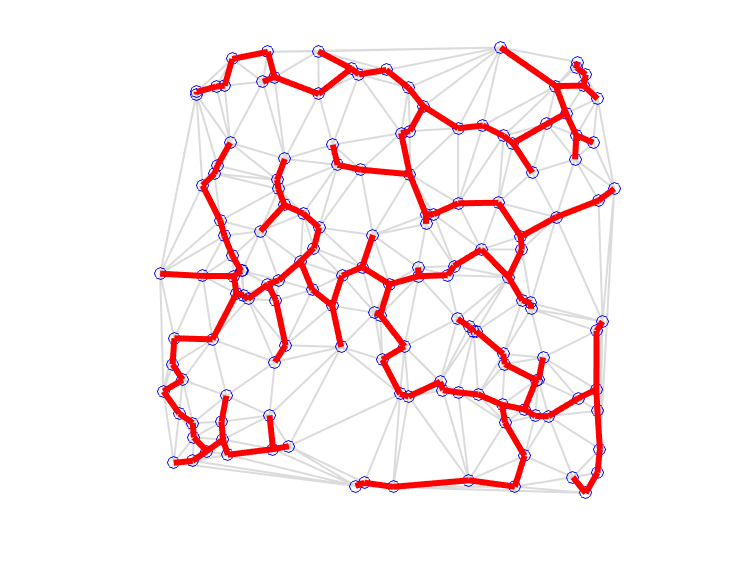

clc,clear
ax=gca;
ax.DataAspectRatio=[1 1 1];
ax.XLim=[0 1];
ax.YLim=[0 1];
ax.XColor='none';
ax.YColor='none';
hold(ax,'on')
DelayTime=.5;

% =========================================================================

rng default
P = rand([150,2]);
DT = delaunayTriangulation(P);
DM = pdist2(P,P);
G=graph(DM);
T=minspantree(G,'Method','sparse');

% 绘制figure 1
for i = 1:size(DT.ConnectivityList,1)
    for i1=1:size(DT.ConnectivityList,2)-1
        for i2=i1+1:size(DT.ConnectivityList,2)
            plot([P(DT.ConnectivityList(i,i1),1),P(DT.ConnectivityList(i,i2),1)]...
                ,[P(DT.ConnectivityList(i,i1),2),P(DT.ConnectivityList(i,i2),2)],'LineWidth',1,'Color',[.86 .86 .86]);
            hold on
        end
    end
end
plot(P(:,1),P(:,2),'bo');
pause(.5)
F=getframe(ax);
[imind,cm]=rgb2ind(F.cdata,256);
imwrite(imind,cm,'Kruskal.gif','gif','Loopcount',inf,'DelayTime',DelayTime);

T1.Edges=sortrows(T.Edges,2);

for j = 0.01:0.01:0.09
    for i = 1:floor(length(T1.Edges.Weight)*j)
        plot([P(T1.Edges.EndNodes(i,1),1),P(T1.Edges.EndNodes(i,2),1)]...
            ,[P(T1.Edges.EndNodes(i,1),2),P(T1.Edges.EndNodes(i,2),2)],'r',"LineWidth",3);
    end
    pause(.5);saveFrame(ax,DelayTime)
end

for j = 0.1:0.1:0.9
    for i = 1:floor(length(T1.Edges.Weight)*j)
        plot([P(T1.Edges.EndNodes(i,1),1),P(T1.Edges.EndNodes(i,2),1)]...
            ,[P(T1.Edges.EndNodes(i,1),2),P(T1.Edges.EndNodes(i,2),2)],'r',"LineWidth",3);
    end
    pause(.5);saveFrame(ax,DelayTime)
end

for j = 0.91:0.01:1
    for i = 1:floor(length(T1.Edges.Weight)*j)
        plot([P(T1.Edges.EndNodes(i,1),1),P(T1.Edges.EndNodes(i,2),1)]...
            ,[P(T1.Edges.EndNodes(i,1),2),P(T1.Edges.EndNodes(i,2),2)],'r',"LineWidth",3);
    end
    pause(.5);saveFrame(ax,DelayTime)
end


function saveFrame(ax,DelayTime)
F=getframe(ax);
[imind,cm]=rgb2ind(F.cdata,256);
imwrite(imind,cm,'kruskal.gif','gif','WriteMode','append','DelayTime',DelayTime);
end